## Preliminaries

clear;close all;clc
% period_of_interest = 1.5:0.0005:1.9;
% indices_of_interest = round(period_of_interest/0.0005) + 1;

distance_range_miles = .1:.1:1; %in miles
velocity_range = 5:5:25; %in mph
datafolder = 'data';

i_des_dist = 1;
i_actual_dist = 2;
i_spd_desired = 3;
i_spd_actual = 4;
i_T_Human = 5;
i_T_Robot = 6;
i_angvel_wheel = 7;
i_des_fatigue_percent = 8;
i_act_fatigue_percent = 9;
i_u_t = 10;

## Plotting Electrical Power

% count = 1;
% % phase_range = 0.4.*(-0.5:0.025:0.5) + 0.3;
% % phase_percents = -50:2.5:50;
% % stiffness_range = 1.8E5.*[0.25,0.5,1,2,4];
% subplot()
% for i = 1:length(distance_range_miles)
%     cur_dist = distance_range_miles(i);
%     for j = 1:length(velocity_range)
%           cur_vel = velocity_range(j);
%           load(strcat(datafolder,'/dist=',num2str(cur_dist),'_vel=',num2str(cur_vel),'.mat'));
%           
%           T_Robot = ans.Data(:,i_T_Robot);
%           F_Robot_on_Ground = T_Robot./.311; %HARDCODED IN WHEEL RADIUS
%           angvel_wheel = ans.Data(:,i_angvel_wheel);
%           cur_Electrical_Power = F_Robot_on_Ground.*angvel_wheel;
%           
%           subplot(length(distance_range_miles),length(velocity_range),count)
%           plot(ans.Time,cur_Electrical_Power)
%           hold on
%           count = count + 1;    
%           title(strcat('dist=',num2str(cur_dist),' vel=',num2str(cur_vel)));
%           ylabel('F_current_exertable (N)');
%           xlabel('time (s)');
%     end
% 
% end
% 
% hold off;


## Plotting Desired Speed and Actual Speed over Time

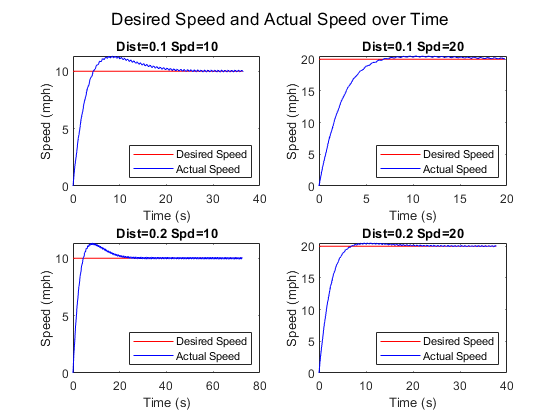

count = 1;
subplot()
for i = 1:length(distance_range_miles)
    cur_dist = distance_range_miles(i);
    for j = 1:length(velocity_range)
          cur_vel = velocity_range(j);
          load(strcat(datafolder,'/dist=',num2str(cur_dist),'_vel=',num2str(cur_vel),'.mat'));

          spd_desired = ans.Data(:,i_spd_desired);
          spd_actual = ans.Data(:,i_spd_actual);
          
          subplot(length(distance_range_miles),length(velocity_range),count)
          plot(ans.Time,spd_desired,'r')
          hold on
          plot(ans.Time,spd_actual,'b')
          legend('Desired Speed', 'Actual Speed', 'Location', 'southeast');
          title(strcat('Dist=',num2str(cur_dist),' Spd=',num2str(cur_vel)));
          ylabel('Speed (mph)');
          xlabel('Time (s)');
          
          count = count + 1;            
    end

end
sgtitle('Desired Speed and Actual Speed over Time');
hold off;

## Plotting Desired and Actual Fatigue Over Time

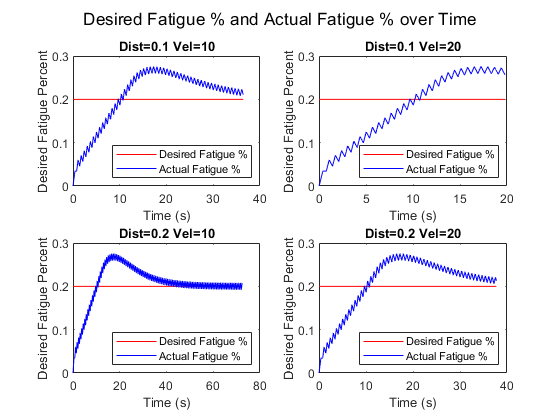

count = 1;
figure()
subplot()
for i = 1:length(distance_range_miles)
    cur_dist = distance_range_miles(i);
    for j = 1:length(velocity_range)
          cur_vel = velocity_range(j);
          load(strcat(datafolder,'/dist=',num2str(cur_dist),'_vel=',num2str(cur_vel),'.mat'));

          des_fatigue_percent = ans.Data(:,i_des_fatigue_percent);
          act_fatigue_percent = ans.Data(:,i_act_fatigue_percent);
          
          subplot(length(distance_range_miles),length(velocity_range),count)
          plot(ans.Time,des_fatigue_percent,'r')
          hold on
          plot(ans.Time,act_fatigue_percent,'b')
          legend('Desired Fatigue %', 'Actual Fatigue %', 'Location', 'southeast');
          title(strcat('Dist=',num2str(cur_dist),' Vel=',num2str(cur_vel)));
          ylabel('Desired Fatigue Percent');
          xlabel('Time (s)');
          
          count = count + 1;            
    end

end
sgtitle('Desired Fatigue % and Actual Fatigue % over Time');
hold off;

## Plotting Human Torque, Robot Torque, and Total Torque over Time

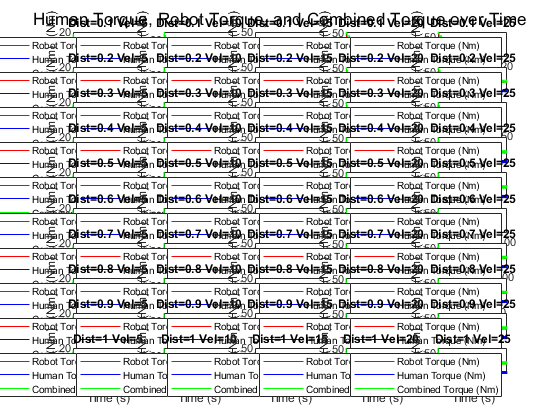

count = 1;
figure()
subplot()
for i = 1:length(distance_range_miles)
    cur_dist = distance_range_miles(i);
    for j = 1:length(velocity_range)
          cur_vel = velocity_range(j);
          load(strcat(datafolder,'/dist=',num2str(cur_dist),'_vel=',num2str(cur_vel),'.mat'));

          T_Robot = ans.Data(:,i_T_Robot);
          T_Human = ans.Data(:,i_T_Human);
          T_Combined = T_Robot + T_Human;
          
          subplot(length(distance_range_miles),length(velocity_range),count)
          plot(ans.Time,T_Robot,'r');
          hold on
          plot(ans.Time,T_Human,'b');
          hold on
          plot(ans.Time,T_Combined,'g');
          legend('Robot Torque (Nm)', 'Human Torque (Nm)', 'Combined Torque (Nm)', 'Location', 'northeast');
          title(strcat('Dist=',num2str(cur_dist),' Vel=',num2str(cur_vel)));
          ylabel('Torque (Nm)');
          xlabel('Time (s)');
          
          count = count + 1;            
    end

end
sgtitle('Human Torque, Robot Torque, and Combined Torque over Time');
hold off;

## Calculating Powers and Heat Map

count = 1;
% figure()
% subplot()
Avg_Electrical_Power = [];
Avg_Human_Power = [];
Avg_Robot_Power = [];
for i = 1:length(distance_range_miles)
    cur_dist = distance_range_miles(i);
    for j = 1:length(velocity_range)
          cur_vel = velocity_range(j);
          load(strcat(datafolder,'/dist=',num2str(cur_dist),'_vel=',num2str(cur_vel),'.mat'));

          T_Robot = ans.Data(:,i_T_Robot);
          F_Robot_on_Ground = T_Robot./.311; %HARDCODED IN WHEEL RADIUS
          angvel_wheel = ans.Data(:,i_angvel_wheel);
          cur_Electrical_Power = F_Robot_on_Ground.*angvel_wheel;
          
          T_Human = ans.Data(:,i_T_Human); %This is on the back tire right?
          F_Human_on_Ground = T_Human./.311; %HARDCODED IN WHEEL RADIUS
          cur_Human_Power = F_Human_on_Ground.*angvel_wheel;
          
          T_Total = T_Robot + T_Human; %This is on the back tire right?
          F_total_on_Ground = T_Total./.311;
          cur_Total_Power = F_total_on_Ground.*angvel_wheel;
          
          act_fatigue_percent = ans.Data(:,i_act_fatigue_percent);
          

%           subplot(length(distance_range_miles),length(velocity_range),count)
%           plot(ans.Time,T_Robot,'r');
%           hold on
%           plot(ans.Time,T_Human,'b');
%           hold on
%           plot(ans.Time,T_Combined,'g');
%           legend('Robot Torque (Nm)', 'Human Torque (Nm)', 'Combined Torque (Nm)', 'Location', 'northeast');
%           title(strcat('Dist=',num2str(cur_dist),' Vel=',num2str(cur_vel)));
%           ylabel('Torque (Nm)');
%           xlabel('Time (s)');
          
          
          Avg_Electrical_Power(i,j) = mean(cur_Electrical_Power);
          Avg_Human_Power(i,j) = mean(cur_Human_Power);  
          Avg_Total_Power(i,j) = mean(cur_Total_Power);
          
          Avg_Fatigue_Percent(i,j) = mean(act_fatigue_percent);
          %row is the same distance
          %column is the same velocity (just like the subplots)
          
          count = count + 1;            
    end

end

Avg_Electrical_Power

Avg_Electrical_Power = 	1.0e+03 *

    0.0065    0.1197    0.5746    1.3774    2.5070
    0.0034    0.0966    0.5231    1.3388    2.5772
    0.0023    0.0887    0.5041    1.3218    2.6073
    0.0017    0.0847    0.4943    1.3125    2.6228
    0.0014    0.0824    0.4885    1.3067    2.6321
    0.0012    0.0808    0.4845    1.3029    2.6383
    0.0010    0.0796    0.4817    1.3001    2.6428
    0.0009    0.0788    0.4796    1.2980    2.6462
    0.0008    0.0781    0.4779    1.2964    2.6488
    0.0007    0.0776    0.4766    1.2951    2.6509


Avg_Human_Power

Avg_Human_Power =    91.7670  129.0145  190.5694  242.5807  295.7266
   96.2744  129.5514  190.9137  249.0318  305.3562
   97.8393  129.5369  192.2638  251.0429  309.4756
   98.8023  129.4084  192.8527  254.1977  311.6557
   99.4364  129.3289  193.0285  254.5270  314.5292
   99.8208  129.4326  193.1039  255.5034  316.4944
  100.0133  129.5149  193.1398  256.0663  316.7899
  100.2073  129.5766  193.2511  256.0778  317.9617
  100.4089  129.5557  193.4448  256.9290  318.9255
  100.5613  129.4990  193.5996  256.7275  318.8944


Avg_Total_Power

Avg_Total_Power = 	1.0e+03 *

    0.0982    0.2487    0.7652    1.6200    2.8028
    0.0997    0.2262    0.7140    1.5879    2.8826
    0.1001    0.2182    0.6963    1.5729    2.9168
    0.1005    0.2142    0.6872    1.5667    2.9344
    0.1008    0.2117    0.6815    1.5613    2.9466
    0.1010    0.2102    0.6776    1.5584    2.9548
    0.1010    0.2091    0.6748    1.5562    2.9596
    0.1011    0.2083    0.6728    1.5541    2.9642
    0.1012    0.2077    0.6714    1.5533    2.9677
    0.1013    0.2071    0.6702    1.5518    2.9698


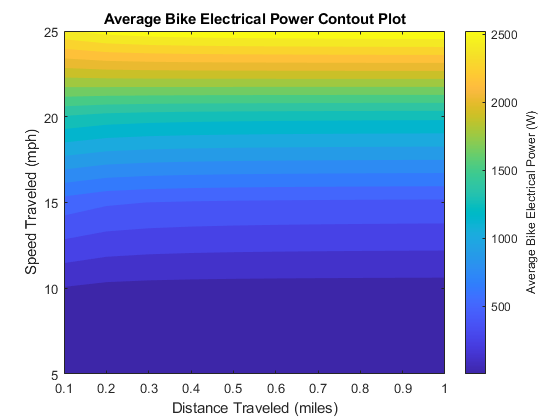


% Countour Plot: Electrical Power Output----------------------
X = distance_range_miles; %in miles
Y = velocity_range; %in mph
[X,Y] = meshgrid(X,Y);
Z = Avg_Electrical_Power';
c = contourf(X,Y,Z,20,'edgecolor', 'none');
h = colorbar;
ylabel(h,'Average Bike Electrical Power (W)')
xlabel('Distance Traveled (miles)')
ylabel('Speed Traveled (mph)')
title('Average Bike Electrical Power Contout Plot')

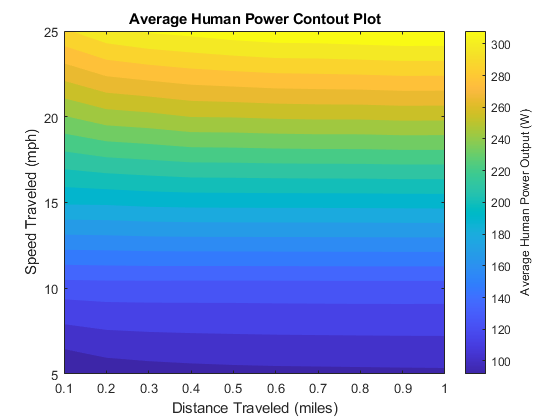


% Countour Plot: Avg Human Power Output----------------------
X = distance_range_miles; %in miles
Y = velocity_range; %in mph
[X,Y] = meshgrid(X,Y);
Z = Avg_Human_Power';
c = contourf(X,Y,Z,20,'edgecolor', 'none');
h = colorbar;
ylabel(h,'Average Human Power Output (W)')
xlabel('Distance Traveled (miles)')
ylabel('Speed Traveled (mph)')
title('Average Human Power Contout Plot')

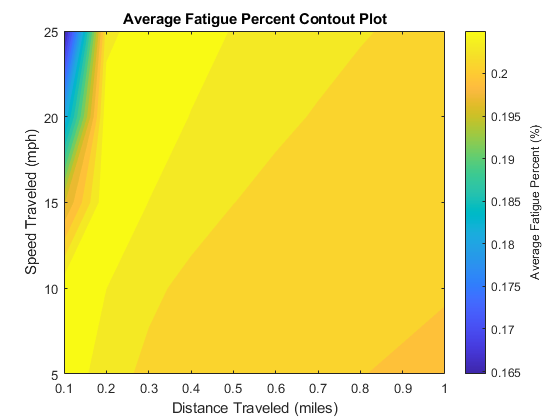


% Countour Plot: Avg Fatigue Percent----------------------
X = distance_range_miles; %in miles
Y = velocity_range; %in mph
[X,Y] = meshgrid(X,Y);
Z = Avg_Fatigue_Percent';
c = contourf(X,Y,Z,20,'edgecolor', 'none');
h = colorbar;
ylabel(h,'Average Fatigue Percent (%)')
xlabel('Distance Traveled (miles)')
ylabel('Speed Traveled (mph)')
title('Average Fatigue Percent Contout Plot')

## image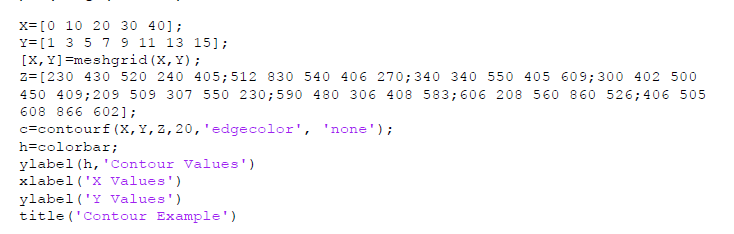

## Extra

% distance_range_miles = .1:.1:.2; %in miles
% velocity_range = 10:10:20; %in mph
% count = 1;
% 
% for i = 1:length(distance_range_miles)
%     cur_dist = distance_range_miles(i);
%     for j = 1:length(velocity_range)
%           cur_vel = velocity_range(j);
%           load(strcat('data/dist=',num2str(cur_dist),'_vel=',num2str(cur_vel),'.mat'));
% 
%           T_Robot = ans.Data(:,i_T_Robot);
%           F_Robot_on_Ground = T_Robot./.311; %HARDCODED IN WHEEL RADIUS
%           angvel_wheel = ans.Data(:,i_angvel_wheel);
%           cur_Electrical_Power = F_Robot_on_Ground.*angvel_wheel;
%           
%           T_Human = ans.Data(:,i_T_Human); %This is on the back tire right?
%           F_Human_on_Ground = T_Human./.311; %HARDCODED IN WHEEL RADIUS
%           cur_Human_Power = F_Human_on_Ground.*angvel_wheel;
%           
%           T_Total = T_Robot + T_Human; %This is on the back tire right?
%           F_total_on_Ground = T_Total./.311;
%           cur_Total_Power = F_total_on_Ground.*angvel_wheel;
%           
% %           subplot(length(distance_range_miles),length(velocity_range),count)
% %           plot(ans.Time,T_Robot,'r');
% %           hold on
% %           plot(ans.Time,T_Human,'b');
% %           hold on
% %           plot(ans.Time,T_Combined,'g');
% %           legend('Robot Torque (Nm)', 'Human Torque (Nm)', 'Combined Torque (Nm)', 'Location', 'northeast');
% %           title(strcat('Dist=',num2str(cur_dist),' Vel=',num2str(cur_vel)));
% %           ylabel('Torque (Nm)');
% %           xlabel('Time (s)');
%           
%         
%           Avg_Electrical_Power(i,j) = mean(cur_Electrical_Power);
%           Avg_Human_Power(i,j) = mean(cur_Human_Power);  
%           Avg_Total_Power(i,j) = mean(cur_Total_Power);
%           %row is the same distance
%           %column is the same velocity (just like the subplots)
%           
%           count = count + 1;            
%     end
% 
% end
% 
% Avg_Electrical_Power
% Avg_Human_Power
% Avg_Total_Power
% 
% % now plot the countour plot
% figure(3)
% X = tendon_stiffness_vec;
% X = linspace(0,100,length(tendon_stiffness_vec));
% 
% Y = freq_stimulation_vec;
% Y = linspace(0,100,length(freq_stimulation_vec));
% 
% 
% [X,Y] = meshgrid(X,Y);
% Z = Avg_Electrical_Power;
% c = contourf(X,Y,Z,20,'edgecolor', 'none');
% h = colorbar;
% ylabel(h,'P_m_e_t (W/kg)')
% xlabel('Tendon Stiffness (%Max)')
% ylabel('Stimulation Frequency (%Max)')
% title('Average Metabolic Rate')
% 
% % sgtitle('Human Torque, Robot Torque, and Total Torque over Time');
% % hold off;

## 3b: Muscle versus Tendon F, V, & P

% phase_range = 0.4.*[0, 0.275, 0.375] + 0.3;
% phase_percents = [0, 0.275, 0.375];
% stiffness_range = 1.8E5.*[0.25,0.5,1,2,4];
% 
% stiffness = 1.8E5;
% for i = 1:length(phase_range)
%     phase = phase_range(i);
%     load(strcat('data/p=',num2str(phase),'_k=',num2str(stiffness),'.mat'));
%     if i == 1
%         data_fvp = zeros(length(phase_range), 7, length(out));
%     end
%     data_fvp(i, :, :) = out(5:11,:);
% end
% 
% time = out(1, :);
% 
% figure("Name", "3b");
% hold on;
% 
% ax_01 = subplot(3, 3, 1);
% plot(period_of_interest, reshape(data_fvp(1, 1, indices_of_interest), [1 801]), "Color", "black");
% ylabel('Force (N)');
% title("0%");
% 
% ax_02 = subplot(3, 3, 2);
% plot(period_of_interest, reshape(data_fvp(2, 1, indices_of_interest), [1 801]), "Color", "black");
% title("27.5%");
% 
% ax_03 = subplot(3, 3, 3);
% plot(period_of_interest, reshape(data_fvp(3, 1, indices_of_interest), [1 801]), "Color", "black");
% title("37.5%");
% 
% ax_04 = subplot(3, 3, 4);
% hold on;
% plot(period_of_interest, -1* reshape(data_fvp(1, 2, indices_of_interest), [1 801]), "Color", "red");
% plot(period_of_interest, -1* reshape(data_fvp(1, 3, indices_of_interest), [1 801]), "Color", "blue");
% plot(period_of_interest, -1* reshape(data_fvp(1, 4, indices_of_interest), [1 801]), "Color", "green");
% ylabel('Velocity (m/s)');
% hold off;
% 
% ax_05 = subplot(3, 3, 5);
% hold on;
% plot(period_of_interest, -1* reshape(data_fvp(2, 2, indices_of_interest), [1 801]), "Color", "red");
% plot(period_of_interest, -1* reshape(data_fvp(2, 3, indices_of_interest), [1 801]), "Color", "blue");
% plot(period_of_interest, -1* reshape(data_fvp(2, 4, indices_of_interest), [1 801]), "Color", "green");
% hold off;
% 
% ax_06 = subplot(3, 3, 6);
% hold on;
% plot(period_of_interest, -1* reshape(data_fvp(3, 2, indices_of_interest), [1 801]), "Color", "red");
% plot(period_of_interest, -1* reshape(data_fvp(3, 3, indices_of_interest), [1 801]), "Color", "blue");
% plot(period_of_interest, -1* reshape(data_fvp(3, 4, indices_of_interest), [1 801]), "Color", "green");
% hold off;
% 
% ax_07 = subplot(3, 3, 7);
% hold on;
% plot(period_of_interest, reshape(data_fvp(1, 5, indices_of_interest), [1 801]), "Color", "red");
% plot(period_of_interest, reshape(data_fvp(1, 6, indices_of_interest), [1 801]), "Color", "blue");
% plot(period_of_interest, reshape(data_fvp(1, 7, indices_of_interest), [1 801]), "Color", "green");
% ylabel('Power (W)');
% hold off;
% 
% ax_08 = subplot(3, 3, 8);
% hold on;
% plot(period_of_interest, reshape(data_fvp(2, 5, indices_of_interest), [1 801]), "Color", "red");
% plot(period_of_interest, reshape(data_fvp(2, 6, indices_of_interest), [1 801]), "Color", "blue");
% plot(period_of_interest, reshape(data_fvp(2, 7, indices_of_interest), [1 801]), "Color", "green");
% xlabel('Time (s)');
% legend(["CE", "SEE", "MTU"], "Location", "south", "NumColumns", 3);
% hold off;
% 
% ax_09 = subplot(3, 3, 9);
% hold on;
% plot(period_of_interest, reshape(data_fvp(3, 5, indices_of_interest), [1 801]), "Color", "red");
% plot(period_of_interest, reshape(data_fvp(3, 6, indices_of_interest), [1 801]), "Color", "blue");
% plot(period_of_interest, reshape(data_fvp(3, 7, indices_of_interest), [1 801]), "Color", "green");
% hold off;
% 
% sgtitle('MTU Component Kinematics at different Phase Delays') 
% 
% linkaxes([ax_01,ax_02,ax_03],'y');
% linkaxes([ax_04,ax_05,ax_06],'y');
% linkaxes([ax_07,ax_08,ax_09],'y');

## 3c: MTU Work by Stiffness

% phase_range = 0.4.*(-0.5:0.025:0.5) + 0.3;
% phase_percents = -50:2.5:50;
% stiffness_range = 1.8E5.*[0.25,0.5,1,2,4];
% 
% for i = 1:length(phase_range)
%     for k = 1:length(stiffness_range)
%         phase = phase_range(i);
%         stiffness = stiffness_range(k);
%         load(strcat('data/p=',num2str(phase),'_k=',num2str(stiffness),'.mat'));
%         
%         if (i == 1 && k == 1)
%             data_power = zeros(1, length(indices_of_interest));
%             data_work_net = zeros(length(phase_range), length(stiffness_range));
%             data_work_pos = zeros(length(phase_range), length(stiffness_range));
%             data_work_neg = zeros(length(phase_range), length(stiffness_range));
%         end
%         data_power = out(i_P_MTU, indices_of_interest);
%         data_work_net(i, k) = trapz(data_power) / 0.4;
%         data_work_pos(i, k) = trapz(data_power(data_power > 0)) / 0.4;
%         data_work_neg(i, k) = trapz(data_power(data_power < 0)) / 0.4;
%     end
% end
% 
% figure("Name", "3c");
% hold on;
% ax_001 = subplot(3, 1, 1);
% bar(phase_percents, data_work_net);
% title('Net Mechanical Work');
% ylabel('Work (J)');
% 
% ax_002 = subplot(3, 1, 2);
% bar(phase_percents, data_work_pos);
% title('Positive Mechanical Work');
% ylabel('Work (J)');
% legend(["4.5E4", "9.0E4", "1.8E5", "3.6E5", "7.2E5"], "Location", "north", "NumColumns", 5);
% 
% ax_003 = subplot(3, 1, 3);
% bar(phase_percents, data_work_neg);
% title('Negative Mechanical Work');
% ylabel('Work (J)');
% xlabel('Muscle stimulation onset phase (%)');
% 
% sgtitle("MTU Work vs. Phase Delay for Different Tendon Stiffnesses");
% %linkaxes([ax_001,ax_002,ax_003],'y');
% hold off;